# Butler Matrix 

a=[ 0 1 2 3].'; % If use ' then it means complex conjugate 
for n=1:180  % Degree
phi=n*pi/180; %Phi radian
x1(n)=[exp(-j*45*pi/180) exp(-j*180*pi/180) exp(+j*45*pi/180) exp(-j*90*pi/180)]*exp(-j*pi*a*cos(phi)); 
x2(n)=[exp(-j*0*pi/180)  exp(-j*45*pi/180) exp(-j*90*pi/180) exp(-j*135*pi/180)]*exp(-j*pi*a*cos(phi)); 
x3(n)=[exp(-j*135*pi/180) exp(-j*90*pi/180) exp(-j*45*pi/180) exp(-j*0*pi/180)]*exp(-j*pi*a*cos(phi)); 
x4(n)=[exp(-j*90*pi/180) exp(+j*45*pi/180) exp(-j*180*pi/180) exp(-j*45*pi/180)]*exp(-j*pi*a*cos(phi)); 
end
exp(-j*pi*a*cos(0))

ans =    1.0000 + 0.0000i
  -1.0000 - 0.0000i
   1.0000 + 0.0000i
  -1.0000 - 0.0000i


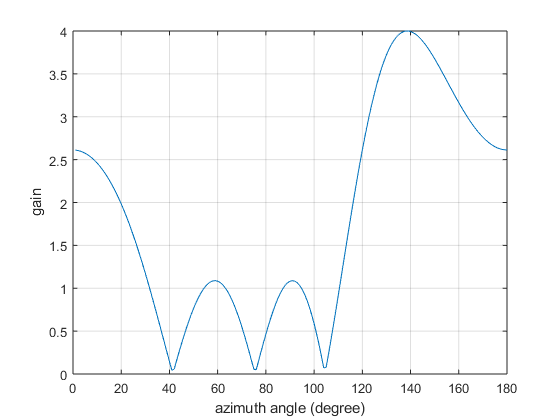


x=[x1; x2; x3; x4]; 
plot((1:180), abs(x1)); 
xlabel('azimuth angle (degree)')
ylabel('gain')
grid 

hold off;
x = [0:0.01:pi];
a1 = sin(x-deg2rad(45));
a2 = sin(x-deg2rad(180));
a3 = sin(x+deg2rad(45));
a4 = sin(x-deg2rad(90));
hold off;

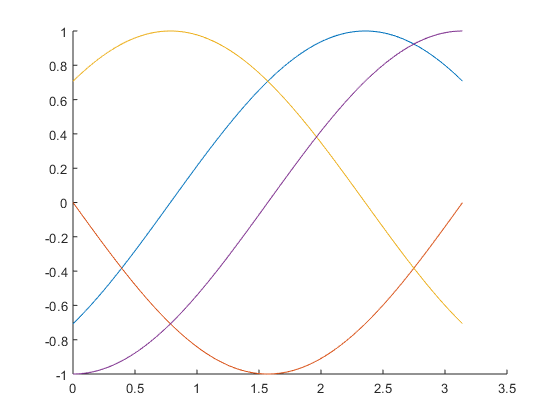

figure
hold on;
plot(x,a1);
plot(x,a2);
plot(x,a3);
plot(x,a4);

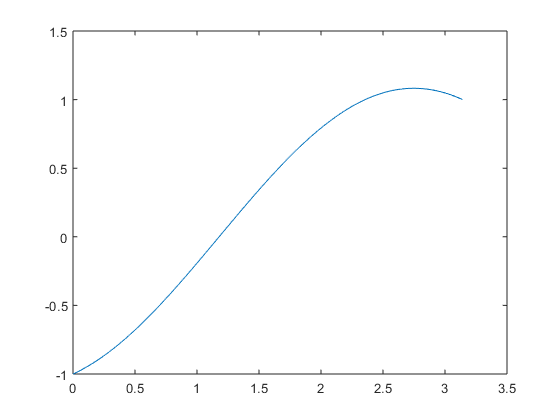

figure
plot(x,a1+a2+a3+a4)